clf;
clear;

finger = imread("../images/fingerprint.tif");
[M,N] = size(finger)

M = 958

N = 798

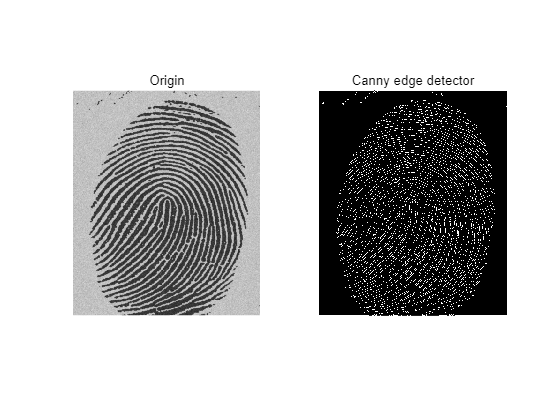

subplot(1,2,1);
imshow(finger);title('Origin');

% Gaussian Filter
sigma = 1;
Gaussian = fspecial('gaussian', [5,5], sigma);
finger_F= imfilter(finger, Gaussian);

% Canny
finger_edge = my_canny(finger_F, 20, 80);

% finger_edge = edge(finger,'canny'); % check

subplot(1,2,2);
imshow(finger_edge);title('Canny edge detector');

function output = my_canny(image, loTh, hiTh)
    [M,N] = size(image);

    % Sobel Mask
    sobel_x = [-1 0 1; -2 0 2; -1 0 1];
    sobel_y = [-1 -2 -1; 0 0 0; 1 2 1];
    image = double(image);
    image_sobel = zeros(M,N);
    image_x = zeros(M,N);
    image_y = zeros(M,N);
    for i = 1:M-2
        for j = 1:N-2
            tmp_x = sobel_x.*image(i:i+2,j:j+2);
            tmp_y = sobel_y.*image(i:i+2,j:j+2);
            tmp_x = sum(tmp_x(:));
            tmp_y = sum(tmp_y(:));
            image_x(i+1,j+1) = tmp_x;
            image_y(i+1,j+1) = tmp_y;
            image_sobel(i+1,j+1) = sqrt(tmp_x^2 + tmp_y^2);
        end
    end
    
    % Nonmaxima Suppression
    index = zeros(M,N);
    for i = 1:M
        for j = 1:N
            ix = image_x(i,j);
            iy = image_y(i,j);
            if (iy<=0 && ix>-iy) || (iy>=0 && ix<-iy)
                index(i,j) = 1;
            elseif (ix>0 && ix<=-iy) || (ix<0 && ix>=-iy)
                index(i,j) = 2;
            elseif (ix<=0 && ix>iy) || (ix>=0 && ix<iy)
                index(i,j) = 3;
            elseif (iy<0 && ix<=iy) || (iy>0 && ix>=iy)
                index(i,j) = 4;
            else
                index(i,j) = 5; % no gradient, not an edge
            end
        end
    end
    
    Gup = zeros(M,N);
    Gdown = zeros(M,N);
    for i = 2:M-1
        for j = 2:N-1
            ix = image_x(i,j);
            iy = image_y(i,j);
            if index(i,j) == 1
                t = abs(iy./ix);
                Gup(i,j) = image_sobel(i,j+1).*(1-t) + image_sobel(i-1,j+1).*t;
                Gdown(i,j) = image_sobel(i,j-1).*(1-t) + image_sobel(i+1,j-1).*t;
            elseif index(i,j) == 2
                t = abs(ix./iy);
                Gup(i,j) = image_sobel(i-1,j).*(1-t) + image_sobel(i-1,j+1).*t;
                Gdown(i,j) = image_sobel(i+1,j).*(1-t) + image_sobel(i+1,j-1).*t;
            elseif index(i,j) == 3
                t = abs(ix./iy);
                Gup(i,j) = image_sobel(i-1,j).*(1-t) + image_sobel(i-1,j-1).*t;
                Gdown(i,j) = image_sobel(i+1,j).*(1-t) + image_sobel(i+1,j+1).*t;
            elseif index(i,j) == 4
                t = abs(iy./ix);
                Gup(i,j) = image_sobel(i,j-1).*(1-t) + image_sobel(i-1,j-1).*t;
                Gdown(i,j) = image_sobel(i,j+1).*(1-t) + image_sobel(i+1,j+1).*t;
            end
        end
    end
    
    G_max = zeros(M,N); % MAX gradient
    for i = 1:M                                     
        for j = 1:N
            if image_sobel(i,j) >= Gup(i,j) && image_sobel(i,j) >= Gdown(i,j)
                G_max(i,j) = image_sobel(i,j);
            end
        end
    end
    
    % thresholding and connectivity analysis
    output = zeros(M,N);
    for i = 2:(M-1)
        for j = 2:(N-1)        
            if G_max(i,j) < loTh
                output(i,j) = 0;
            elseif G_max(i,j) > hiTh
                output(i,j) = 1;
            else
                temp =[G_max(i-1,j-1), G_max(i-1,j), G_max(i-1,j+1);
                       G_max(i,j-1),   G_max(i,j),   G_max(i,j+1);
                       G_max(i+1,j-1), G_max(i+1,j), G_max(i+1,j+1)];
                temMax = max(temp);
                if temMax(1) > hiTh
                    output(i,j) = 1;
                else
                    output(i,j) = 0;
                end
            end
        end
    end
end